
clear; clc;

## 产生数据


x = [0.01:0.01:1;1:-0.01:0.01]';

y = (x(:,1).^2+x(:,2).^2)/2 ;




## 训练神经网络

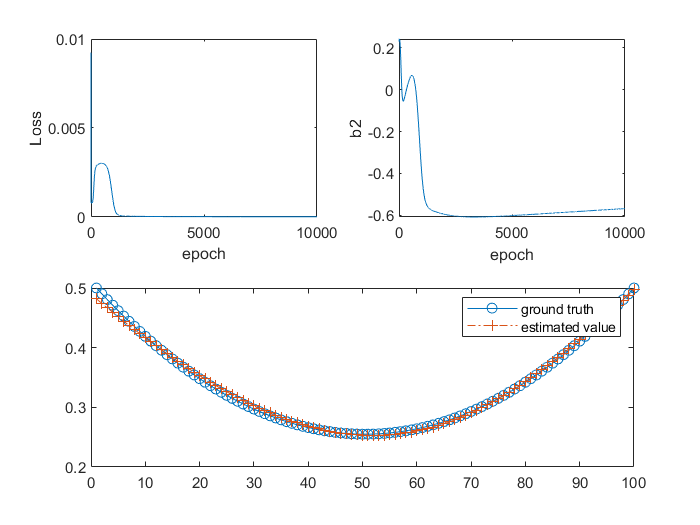

% 输入，隐层，输出维数
d0 = 2; d1 = 3; d2 = 1;

%  初始化W1,W2,b1,b2
W1 = 0.1*randn(d1,d0);
b1 = 0.1*randn(d1,1);
W2 = 0.1*randn(d2,d1);
b2 = 0.1*randn(d2,1);


for ii = 1 : 10000  % 迭代10000个epoch
    % 采用随机梯度的方法，对每个样本调整一次权值，每个epoch，将样本先随机打乱次序进行训练
    P = 1:100;
    X = x(P,:);
    Y = y(P);
    

    alpha = 0.1;
    
    % 针对每个打乱次序的样本调整权值
    for i = 1 : 100 
        Z1 = W1 * X(i,:)'+b1;
        h = mysigmoid(Z1);
        Z2 = W2 * h + b2;
        y_out = Z2;
        loss(i) = norm(Y(i)-y_out)^2;
        % 计算梯度
        [delta2_W2,delta2_b2,delta1_W1,delta1_b1] = my_grad_linear_output(X(i,:)',y_out,Y(i),Z1,Z2,W2,d0,d1,d2);
        % 权值更新
        W1 = W1 - alpha* delta1_W1;
        b1 = b1 - alpha* delta1_b1';
        W2 = W2 - alpha* delta2_W2;
        b2 = b2 - alpha* delta2_b2;
    end
    % 记下b2，一维的好画图
    b(ii) = b2;
    % 计算Loss
    loss_epoch(ii) = 1/100*sum(loss);

end

%% 测试
for i = 1 : 100
    Z1 = W1 * x(i,:)'+b1;
    h = mysigmoid(Z1);
    Z2 = W2 * h + b2;
    y_out(i) = Z2; 
end

subplot(2,2,1)
plot(loss_epoch)
ylabel('Loss')
xlabel('epoch')
subplot(2,2,2)
plot(b)
xlabel('epoch')
ylabel('b2')
subplot(2,1,2)
plot(y,'o-')
hold on
plot(y_out,'+-.')
legend('ground truth','estimated value')